## Simulation of 3 LIMOs following a target in a V shape formation

The localization problem is solved using an EKF. 

Available sensors: lidar, camera, IMU, encoders.

In this simulation in order to deal with a simple situation we can consider to have the first limo that follows the person (it tries to keep a fixed distance from the person walking, for example using a simple PD controller and moves always in direction of the person, so the shortest path). The other 2 limos try to keep a particular position respect to the first limo, so always on its back, one on the left and one on the right.

For what concerns the measurements we assume that the first limo can measure directly its position using the lidar (measurement model of the lidar is an identity matrix) and the person position using the camera, so it knows always the position of the target. The 2 following limos know their position using lidar, again identity matrix as measurement model for lidar, and they know also the position of the first limo, computed from the first using an EKF.

So basically each limo implements its own EKF to determine the position, the first sends the computed position to the other 2 and the control is implemented by using a simple PD controller.

clc;
close all;
clear all;

% Function used for the EKF


% System model
function [x_next, y_next, theta_next, w, v] = ...
    f(x, y, theta, dt, w_l, w_r, w_i, w1, w2, params)
    
    % Limo params
    r = params.r;
    b = params.b;

    % Linear velocity and yaw rate
    v = (w_l + w_r) * r/2;
    w = w1 * (w_r - w_l) * r/b + w2 * w_i;

    % State prediction
    x_next = x + dt*v*cos(theta + dt*w/2);
    y_next = y + dt*v*sin(theta + dt*w/2);
    theta_next = theta + dt*w;

end

% A matrix, jacobian of f respect to the states
function A = sys_j(v, w, theta, dt)
    A = [1, 0, -dt*v*sin(theta + dt*w/2);
         0, 1, dt*v*cos(theta + dt*w/2);
         0, 0, 1];
end

% G matrix, jacobian of f respect to noises
function G = in_j(v, w, theta, dt, w1, w2)
    G = [dt*cos(theta + dt*w/2), -dt^2 * v/2 * w1 * sin(theta + dt*w/2), -dt^2 * v/2 * w2 * sin(theta + dt*w/2);
         dt*sin(theta + dt*w/2), +dt^2 * v/2 * w1 * cos(theta + dt*w/2), +dt^2 * v/2 * w2 * cos(theta + dt*w/2);
         0, dt * w1, dt * w2];
end

% H matrix, measurement model 
function H = meas_j()
    H = eye(3);
end

% Functions used for the controller

function [w_r, w_l, w_imu, x_lidar, y_lidar, theta_lidar] = ...
    ctrlL1(state, x_target, y_target, Kp, L3, params, dt, w1, w2)
    
    x = state(1);
    y = state(2);
    theta = state(3);
    r = params.r;
    b = params.b;

    dist = sqrt((x_target - x)^2 + (y_target - y)^2) - L3;
    dtheta = atan2(y_target - y, x_target - x);
    v = Kp * dist;
    w = Kp * dtheta;

    w_r = (v + w * b / 2) / r;
    w_l = (v - w * b / 2) / r;
    w_imu = w;

    [x_lidar, y_lidar, theta_lidar, w, v] = ...
    f(x, y, theta, dt, w_l, w_r, w_imu, w1, w2, params);

end


function [w_r, w_l, w_imu, x_lidar, y_lidar, theta_lidar] = ...
    ctrlL23(state, stateL1, x_target, y_target, Kp, L1, L2, params, dt, w1, w2)
    
    x = state(1);
    y = state(2);
    theta = state(3);
    xL1 = stateL1(1);
    yL1 = stateL1(2);
    thetaL1 = stateL1(3);
    r = params.r;
    b = params.b;

    %to be changed

    [x_lidar, y_lidar, theta_lidar, w, v] = ...
    f(x, y, theta, dt, w_l, w_r, w_imu, w1, w2, params);

end

% Simulation data:

% Samling period / controller period
dt = 0.01;

% Simulation steps
N = 1000;

% Time axis
t = 0:dt:(N-1)*dt;

% Trajectory of the target
x_target = t;
y_target = t.^2;

% Controller params
Kp = 4;

% Simulation

% Formation params: L1 -> distance along the x axis of limo 1
                  % L2 -> distance along y axis of limo 1 (+/- for the 2 limos) 
                  % L3 -> distance between limo 1 and target

L1 = 0.5;
L2 = 0.5;
L3 = 1;

% Initial state
s0L1 = [-L3, 0, 0];
s0L2 = [-L1 - L3, L2, 0];
s0L3 = [-L1 - L3, -L2, 0];

% Data (founded online)
params.r = 0.033;
params.b = 0.162;

% Model covariance
Q = diag([1e-4, 1e-4, 1e-4]);

% Measures covariance
R = diag([1e-4, 1e-4, 1e-4]);

% Initalization of state estimate and matricies
s_estL1 = zeros(3, length(t));
s_estL2 = zeros(3, length(t));
s_estL3 = zeros(3, length(t));
s_estL1(:, 1) = s0L1.';
s_estL2(:, 1) = s0L2.';
s_estL3(:, 1) = s0L3.';
H = meas_j();
PL1 = inv(H.' * inv(R) * H);
PL2 = inv(H.' * inv(R) * H);
PL3 = inv(H.' * inv(R) * H);

% Weights to calculate omega using encoders and IMU
w1 = 1; 
w2 = 0; 

% Linear velocity and yaw rate
wL1 = zeros(1, length(t));
wL2 = zeros(1, length(t));
wL3 = zeros(1, length(t));
vL1 = zeros(1, length(t));
vL2 = zeros(1, length(t));
vL3 = zeros(1, length(t));

% Input applied
w_imuL1 = 0;
w_imuL2 = 0;
w_imuL3 = 0;
w_rL1 = 0;
w_lL1 = 0;
w_rL2 = 0;
w_lL2 = 0;
w_rL3 = 0;
w_lL3 = 0;
x_lidarL1 = 0;
y_lidarL1 = 0;
theta_lidarL1 = 0;
x_lidarL2 = -L1;
y_lidarL2 = L2;
theta_lidarL2 = 0;
x_lidarL3 = -L1;
y_lidarL3 = -L2;
theta_lidarL3 = 0;

for i = 1:N-1
    
    % Prediction step:
    % limo1
    [s_estL1(1, i+1), s_estL1(2, i+1), s_estL1(3, i+1), wL1(i), vL1(i)]...
        = f(s_estL1(1, i), s_estL1(2, i), s_estL1(3, i),...
        dt, w_lL1, w_rL1, w_imuL1, w1, w2, params);

    AL1 = sys_j(vL1(i), wL1(i), s_estL1(3, i), dt);
    GL1 = in_j(vL1(i), wL1(i), s_estL1(3, i), dt, w1, w2);
    H = meas_j();
    PL1 = AL1 * PL1 * AL1.' + GL1 * Q * GL1.';

    % limo2
    [s_estL2(1, i+1), s_estL2(2, i+1), s_estL2(3, i+1), wL2(i), vL2(i)]...
    = f(s_estL2(1, i), s_estL2(2, i), s_estL2(3, i),...
    dt, w_lL2, w_rL2, w_imuL2, w1, w2, params);

    AL2 = sys_j(vL2(i), wL2(i), s_estL2(3, i), dt);
    GL2 = in_j(vL2(i), wL2(i), s_estL2(3, i), dt, w1, w2);
    H = meas_j();
    PL2 = AL2 * PL2 * AL2.' + GL2 * Q * GL2.';

    % limo3
    [s_estL3(1, i+1), s_estL3(2, i+1), s_estL3(3, i+1), wL3(i), vL3(i)]...
    = f(s_estL3(1, i), s_estL3(2, i), s_estL3(3, i),...
    dt, w_lL3, w_rL3, w_imuL3, w1, w2, params);

    AL3 = sys_j(vL3(i), wL3(i), s_estL3(3, i), dt);
    GL3 = in_j(vL3(i), wL3(i), s_estL3(3, i), dt, w1, w2);
    H = meas_j();
    PL3 = AL3 * PL3 * AL3.' + GL3 * Q * GL3.';

    % Update step:
    % limo1
    SL1 = H * PL1 * H.' + R;
    WL1 = PL1 * H.' * inv(SL1);
    s_estL1(:, i+1) = s_estL1(:, i+1) + WL1 * ([x_lidarL1; y_lidarL1; theta_lidarL1] - s_estL1(:, i+1));
    PL1 = (eye(3) - WL1 * H) * PL1;

    % limo2
    SL2 = H * PL2 * H.' + R;
    WL2 = PL2 * H.' * inv(SL2);
    s_estL2(:, i+1) = s_estL2(:, i+1) + WL2 * ([x_lidarL2; y_lidarL2; theta_lidarL2] - s_estL2(:, i+1));
    PL2 = (eye(3) - WL2 * H) * PL2;

    % limo3
    SL3 = H * PL3 * H.' + R;
    WL3 = PL3 * H.' * inv(SL3);
    s_estL3(:, i+1) = s_estL3(:, i+1) + WL3 * ([x_lidarL3; y_lidarL3; theta_lidarL3] - s_estL3(:, i+1));
    PL3 = (eye(3) - WL3 * H) * PL3;

    % Controller
    % limo 1
    [w_rL1, w_lL1, w_imuL1, x_lidarL1, y_lidarL1, theta_lidarL1] = ...
    ctrlL1(s_estL1(:, i+1), x_target(i+1), y_target(i+1), Kp, L3, params, dt, w1, w2);

    % limo 2
    

end

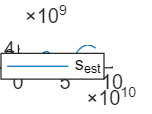

% Plots

figure(1), hold on;
plot(s_estL1(1,:), s_estL1(2,:));
legend('s_{est}');
hold off;

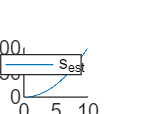


figure(2), hold on;
plot(x_target, y_target);
legend('s_{est}');
hold off;